# Retinal Area Comparisons

## Humans: Initialize Variables

clear all
addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

species='Humans';

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 3; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','V7','LO1','LO2','TO1','TO2'};
allparietal_numbers=1:7;
allparietal_labels={'IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};
allfrontal_numbers=1:2;
allfrontal_labels={'FEF','IFS'};
% allLGN_numbers = 1;
% allLGN_labels={'LGN'};
% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_human=1:6; EVCcolor=[0 0 1];
V4rois_human=7; V4color=[1 0 1];
ventralrois_human=8:11; ventralcolor=[1 0 0];
dorsalrois_human=12:14; dorsalcolor=[1 .6 0]; % added V7, idk if that's right
lateralrois_human=15:18; lateralcolor=[0 1 0];
parietalrois_human=19:25; parietalcolor=[0 1 1];
frontalrois_human=26:27; frontalcolor=[.5 .1 .5];
% LGNrois=28; LGNcolor=[1 1 0];
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human;frontalrois_human};%LGNrois};
all_labels_human=[allvisual_labels, allparietal_labels, allfrontal_labels];%, allLGN_labels];
use_colorscale_human=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,length(dorsalrois_human),1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1);...
    repmat(frontalcolor,length(frontalrois_human),1)];
%     repmat(LGNcolor,1,1)];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human = flipud(use_colorscale_human);

nodearea_smoothwm_col=2;
nodearea_pial_col=3;


## Humans: Extract Data from Files

% This should be a more efficient way of filtering the directories:
files = dir(data_dir);
names = {files.name}; 
dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
subjs=names(dirFlags);
norois=[];

% retino_surfacearea outputs are 1x2 cells (hemispheres) each 18x62 (brain area x
% subject), total_surfacearea is sum of all brain areas 1x2 cell each 1x62
[retino_surfacearea_total,retino_surfacearea_smoothwm,retino_surfacearea_pial,...
    parietal_surfacearea_total,parietal_surfacearea_smoothwm,parietal_surfacearea_pial,...
    frontal_surfacearea_total,frontal_surfacearea_smoothwm,frontal_surfacearea_pial,...
    LGN_surfacearea] = getSubjData_human(subjs,species,plot_indiv_subj,...
    allvisual_numbers,allparietal_numbers,allfrontal_numbers,nodearea_smoothwm_col,nodearea_pial_col);

No allparietal in abma
No allfrontal in abma
No allparietal in amar
No allfrontal in amar
No allparietal in ccha
No allfrontal in ccha
No allparietal in csai
No allfrontal in csai
No allparietal in dbou
No allfrontal in dbou
No allparietal in ebou
No allfrontal in ebou
No allparietal in ebow
No allfrontal in ebow
No allparietal in fper
No allfrontal in fper
No allfrontal in gdet
No allparietal in heyu
No allfrontal in heyu
No allparietal in ifie
No allfrontal in ifie
No allparietal in jche
No allfrontal in jche
No allparietal in jfan
No allfrontal in jfan
No allparietal in jwhi
No allfrontal in jwhi
No allparietal in lsil
No allfrontal in lsil
No allparietal in lwan
No allfrontal in lwan
No allparietal in mfog
No allfrontal in mfog
No allparietal in mkug
No allfrontal in mkug
No allparietal in mlob
No allfrontal in mlob
No allparietal in skhe
No allfrontal in skhe
No allparietal in tsco
No allfrontal in tsco


## Humans: Calculate Averages Based on Metric

area_metric = 3;
for i = 1:2
    surfacearea_total{i} = retino_surfacearea_total{i} + parietal_surfacearea_total{i} + frontal_surfacearea_total{i};
    surfacearea_smoothwm{i} = [retino_surfacearea_smoothwm{i};parietal_surfacearea_smoothwm{i};frontal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [retino_surfacearea_pial{i};parietal_surfacearea_pial{i};frontal_surfacearea_pial{i}];
end

total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);
surfacearea_avg{1} = [surfacearea_avg{1};LGN_surfacearea{1}];
surfacearea_avg{2} = [surfacearea_avg{2};LGN_surfacearea{2}];

if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_human = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_human = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_human = surfacearea_avg;
end

surfacearea_human{1}(14,:) = [];
surfacearea_human{2}(14,:) = [];

## Humans: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas

V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis(7,:);

v_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis(8:end,:)];

ventral_combined_human = mean(v_human(ventralrois_human-3,:),1);
dorsal_combined_human = mean(v_human(dorsalrois_human(1:2)-3,:),1);
lateral_combined_human = mean(v_human(lateralrois_human-3,:),1);
parietal_combined_human = mean(v_human(parietalrois_human-3,:),1);
frontal_combined_human = mean(v_human(frontalrois_human-3,:),1);
% LGN_combined_human = mean(v_human(LGNrois-3,:),1);

v_combined_human = [v_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human;frontal_combined_human];%LGN_combined_human];

%combined hemis V1
normv1_human = v_human./V1_bothhemis_combined;

normventral_combined_human = mean(normv1_human(ventralrois_human-3,:),1);
normdorsal_combined_human = mean(normv1_human(dorsalrois_human(1:2)-3,:),1);
normlateral_combined_human = mean(normv1_human(lateralrois_human-3,:),1);
normparietal_combined_human = mean(normv1_human(parietalrois_human-3,:),1);
normfrontal_combined_human = mean(normv1_human(frontalrois_human-3,:),1);
% normLGN_combined_human = mean(normv1_human(LGNrois-3,:),1);

normv1_combined_human = [normv1_human(1:4,:);normventral_combined_human;normdorsal_combined_human;...
    normlateral_combined_human;normparietal_combined_human;normfrontal_combined_human];%normLGN_combined_human];

use_colorscale_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];%LGNcolor];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human = flipud(use_colorscale_human);

alllabels_humans = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal','Frontal'};%,'LGN'};


## Monkeys: Initialize Variables

species='Monks';

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 1; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,100,101,102,103,52,53,54,55,56];
all_labels_monkey={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       
EVCrois_monkey=1:6; EVCcolor=[0 0 1];
V4rois_monkey=7:10; V4color=[1 0 1];
ventralrois_monkey=11:15; ventralcolor=[1 0 0];
dorsalrois_monkey=16:17; dorsalcolor=[1 .6 0];
lateralrois_monkey=18:21; lateralcolor=[0 1 0];
parietalrois_monkey=22:26; parietalcolor=[0 1 1];
allrois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
use_colorscale_monkey=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1)];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');


## Monkeys: Extract Data from Files

% This should be a more efficient way of filtering the directories:
files = dir(data_dir);
names = {files.name}; 
dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
subjs=names(dirFlags);
norois=[];

[retino_surfacearea_total,retino_surfacearea_smoothwm,retino_surfacearea_pial] = getSubjData( ...
    subjs,species,plot_indiv_subj,allvisual_numbers,nodearea_smoothwm_col,nodearea_pial_col);

Error Read_1D:
 ./Monks/baby5/rh.thickness.1D.dset not found
Error Read_1D:
 ./Monks/baby5/lh.thickness.1D.dset not found


## Monkeys: Calculate Averages Based on Metric

for i = 1:2
    surfacearea_total{i} = retino_surfacearea_total{i};
    surfacearea_smoothwm{i} = retino_surfacearea_smoothwm{i};
    surfacearea_pial{i} = retino_surfacearea_pial{i};
end

total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_monkey = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_monkey = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_monkey = surfacearea_avg;
end


## Monkeys: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas

V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis(9:10,:),1);

v_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis(11:end,:)];

EVCrois_monkey=1:3;
V4rois_monkey=4:5;
ventralrois_monkey=6:10;
dorsalrois_monkey=11:12;
lateralrois_monkey=13:16;
parietalrois_monkey=17:21;

V4_combined_monkey = mean(v_monkey(4:5,:),1);
ventral_combined_monkey = mean(v_monkey(ventralrois_monkey-5,:),1);
dorsal_combined_monkey = mean(v_monkey(dorsalrois_monkey-5,:),1);
lateral_combined_monkey = mean(v_monkey(lateralrois_monkey-5,:),1);
parietal_combined_monkey = mean(v_monkey(parietalrois_monkey-5,:),1);

v_combined_monkey = [v_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];

%combined hemis V1
normv1_monkey = v_monkey./V1_bothhemis_combined;

normV4_combined_monkey = mean(normv1_monkey(4:5,:),1);
normventral_combined_monkey = mean(normv1_monkey(ventralrois_monkey-5,:),1);
normdorsal_combined_monkey = mean(normv1_monkey(dorsalrois_monkey-5,:),1);
normlateral_combined_monkey = mean(normv1_monkey(lateralrois_monkey-5,:),1);
normparietal_combined_monkey = mean(normv1_monkey(parietalrois_monkey-5,:),1);

normv1_combined_monkey = [normv1_monkey(1:3,:);normV4_combined_monkey;normventral_combined_monkey;...
    normdorsal_combined_monkey;normlateral_combined_monkey;normparietal_combined_monkey];

use_colorscale_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');
use_colorscale_inv_monkey = flipud(use_colorscale_monkey);

alllabels_monkeys = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_combined = {'V1','V1','V2','V2','V3','V3','V4','V4','Ventral','Ventral','Dorsal','Dorsal','Lateral','Lateral','Parietal','Parietal','Frontal','','LGN'};

## Fig 2A: Plot Raw Surface Area Comparisons

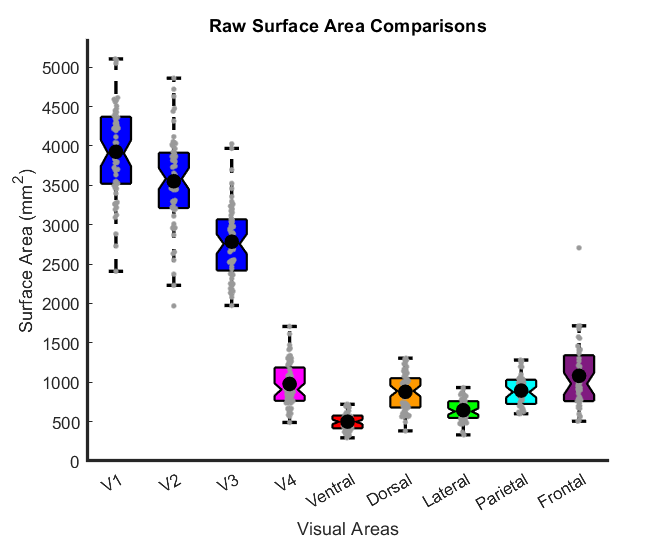

figure
hold on
h1=boxplot(v_combined_human','positions',1:2:size(v_combined_human,1)*2,'notch','on','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(v_combined_human,1)
   patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_inv_human(j,:),'FaceAlpha',1);
end
plotSpread(v_combined_human','xValues',1:2:size(v_combined_human,1)*2,'distributionColors',use_colorscale_human*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(v_combined_human,1)*2,nanmean(v_combined_human'),'k.','MarkerSize',30);
% xlim([0.5 size(normv1_combined_human,1)+.5])

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:2:length(alllabels_humans)*2],'xticklabel', alllabels_humans);
xlabel('Visual Areas');
ylabel('Surface Area (mm^2)');
title('Raw Surface Area Comparisons')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

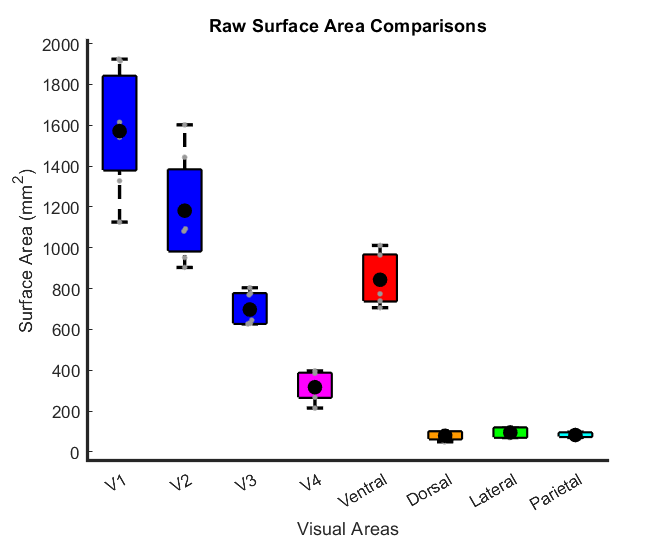



figure
hold on
h2=boxplot(v_combined_monkey','positions',1:2:size(v_combined_monkey,1)*2,'notch','off','colors',[0 0 0],'symbol','');
set(h2,{'linew'},{2})
h2 = findobj(gca,'Tag','Box');
for j=1:size(v_combined_monkey,1)
   patch(get(h2(j),'XData'),get(h2(j),'YData'),use_colorscale_inv_monkey(j,:),'FaceAlpha',1);
end
plotSpread(v_combined_monkey','xValues',1:2:size(v_combined_monkey,1)*2,'distributionColors',use_colorscale_monkey*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(v_combined_monkey,1)*2,nanmean(v_combined_monkey'),'k.','MarkerSize',30);
hold on

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:2:length(alllabels_monkeys)*2],'xticklabel', alllabels_monkeys);
xlabel('Visual Areas');
ylabel('Surface Area (mm^2)');
title('Raw Surface Area Comparisons')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

## Fig 2B: Plot Normalized Surface Area Comparisons

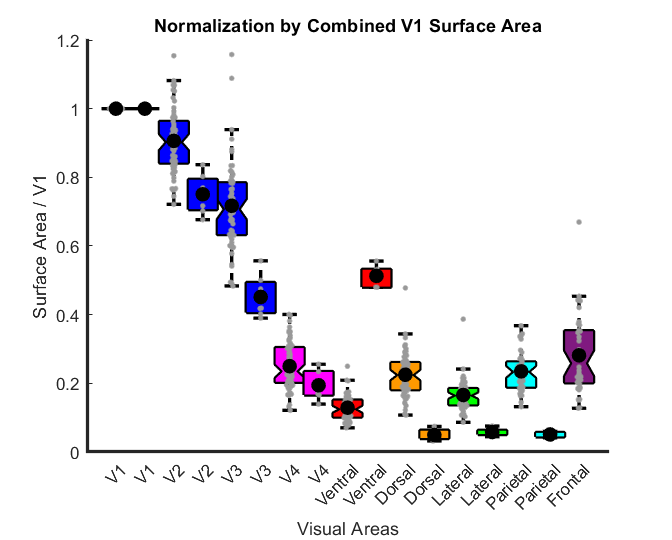

figure
hold on
h1=boxplot(normv1_combined_human','positions',1:2:size(normv1_combined_human,1)*2,'notch','on','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(normv1_combined_human,1)
   patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_inv_human(j,:),'FaceAlpha',1);
end
plotSpread(normv1_combined_human','xValues',1:2:size(normv1_combined_human,1)*2,'distributionColors',use_colorscale_human*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(normv1_combined_human,1)*2,nanmean(normv1_combined_human'),'k.','MarkerSize',30);
% xlim([0.5 size(normv1_combined_human,1)+.5])

h2=boxplot(normv1_combined_monkey','positions',2:2:size(normv1_combined_monkey,1)*2,'notch','off','colors',[0 0 0],'symbol','');
set(h2,{'linew'},{2})
h2 = findobj(gca,'Tag','Box');
for j=1:size(normv1_combined_monkey,1)
   patch(get(h2(j),'XData'),get(h2(j),'YData'),use_colorscale_inv_monkey(j,:),'FaceAlpha',1);
end
plotSpread(normv1_combined_monkey','xValues',2:2:size(normv1_combined_monkey,1)*2,'distributionColors',use_colorscale_monkey*0+[.6 .6 .6],'spreadWidth',.5)
plot(2:2:size(normv1_combined_monkey,1)*2,nanmean(normv1_combined_monkey'),'k.','MarkerSize',30);
% xlim([0.5 size(normv1_combined_monkey,1)+.5])
hold on

xt = sort([1:2:size(normv1_combined_human,1)*2,2:2:size(normv1_combined_monkey,1)*2]);

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',xt,'xticklabel', alllabels_combined);
xlabel('Visual Areas');
ylabel('Surface Area / V1');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 1.2])

pngFileName = ('Normalization_CombinedV1.png');
fullFileName = fullfile(save_folder, pngFileName);
% saveas(gcf, fullFileName);

## Supplementary Fig: Plot Cross-hemisphere Correlations

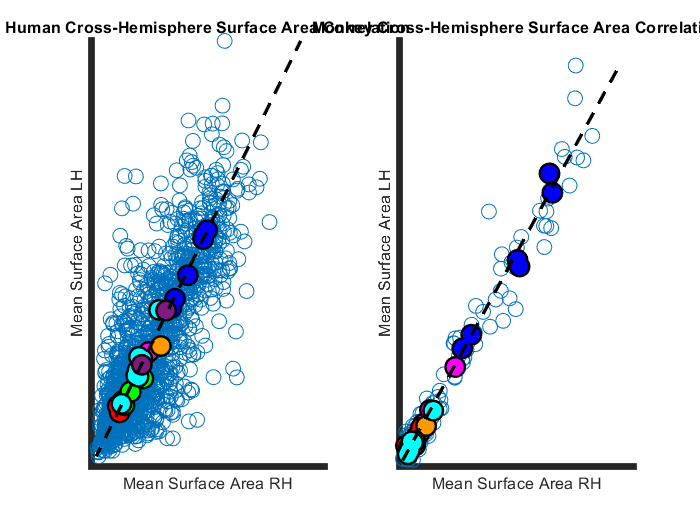

allrois_human{4} = allrois_human{4}(1:2);allrois_human{5} = allrois_human{5}-1;allrois_human{6} = allrois_human{6}-1;allrois_human{7} = allrois_human{7}-1;

figure()
subplot(1,2,1)
scatter(surfacearea_human{1}(:),surfacearea_human{2}(:),80);
hold on
for rr = 1:length(allrois_human)
    plot(nanmean(surfacearea_human{1}(allrois_human{rr},:),2),nanmean(surfacearea_human{2}(allrois_human{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_human{1}(allrois_human{rr},:),2),nanmean(surfacearea_human{2}(allrois_human{rr},:),2),'.','Color',use_colorscale_unique_human(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_human{1}(:)),max(surfacearea_human{2}(:))]);
min_value=floor([min(surfacearea_human{1}(:)),min(surfacearea_human{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])
title('Human Cross-Hemisphere Surface Area Correlation')


subplot(1,2,2)
scatter(surfacearea_monkey{1}(:),surfacearea_monkey{2}(:),80);
hold on
for rr = 1:length(allrois_monkey)
    plot(nanmean(surfacearea_monkey{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(allrois_monkey{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_monkey{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(allrois_monkey{rr},:),2),'.','Color',use_colorscale_unique_monkey(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_monkey{1}(:)),max(surfacearea_monkey{2}(:))]);
min_value=floor([min(surfacearea_monkey{1}(:)),min(surfacearea_monkey{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');

title('Monkey Cross-Hemisphere Surface Area Correlation')
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])

## Supplementary Fig: Comparing Cross-Species Normalized Area Sizes

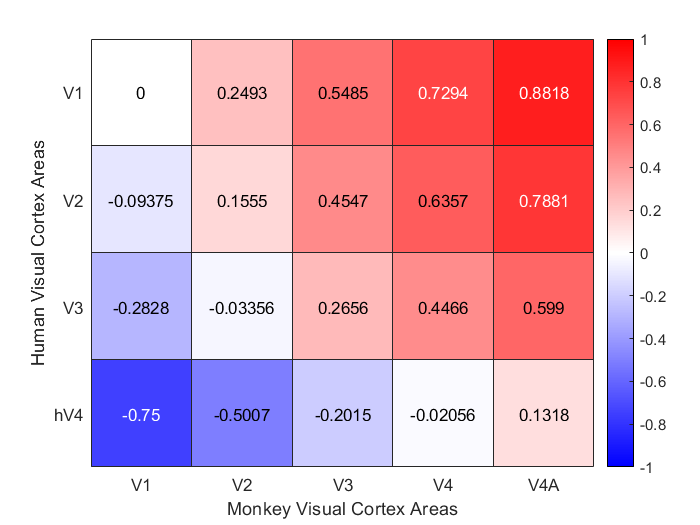

VCrois_human = {'V1','V2','V3','hV4'};
VCrois_monkey = {'V1','V2','V3','V4','V4A'};

nhuman = length(VCrois_human);
nmonkey = length(VCrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(hh,:),'omitnan');
        avgmonkey = mean(normv1_monkey(mm,:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
    end
end

yvalues = VCrois_human;
xvalues = VCrois_monkey;

figure;
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-1 1]);
xlabel('Monkey Visual Cortex Areas')
ylabel('Human Visual Cortex Areas')
saveas(gcf,[save_folder,'\CrossSpecies\visual_diff.png'])

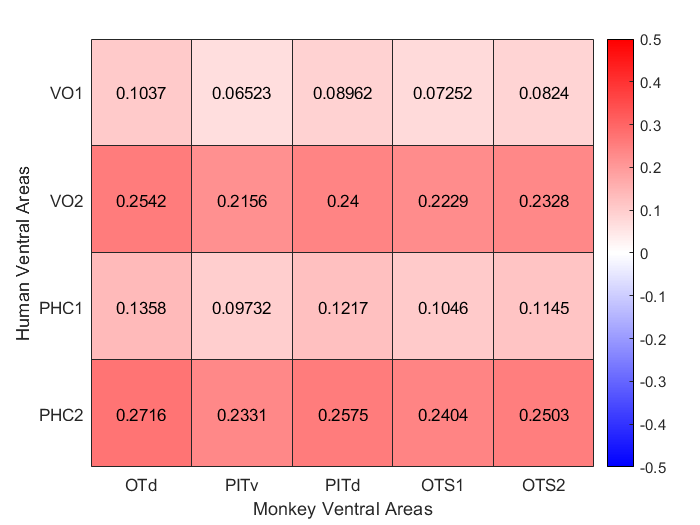

saveas(gcf,[save_folder,'\CrossSpecies\visual_diff.fig'])


% ventral rois
nhuman = length(ventralrois_human);
nmonkey = length(ventralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(ventralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(ventralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
    end
end

yvalues = all_labels_human(ventralrois_human);
xvalues = all_labels_monkey(ventralrois_monkey+5);

figure;
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Ventral Areas')
ylabel('Human Ventral Areas')
saveas(gcf,[save_folder,'\CrossSpecies\ventral_diff.png'])

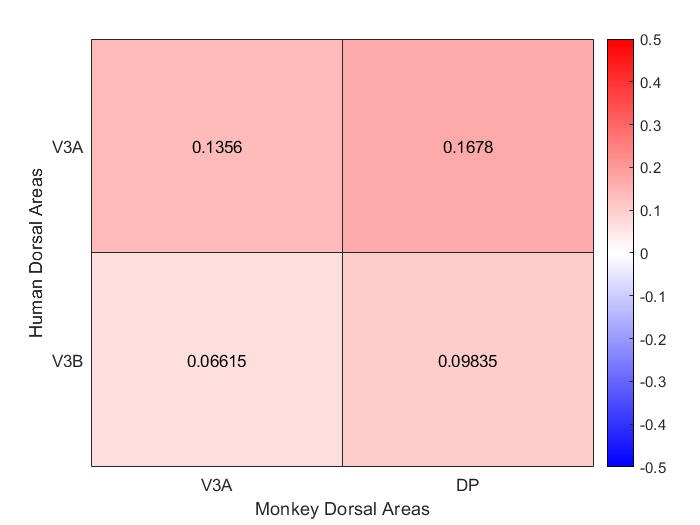

saveas(gcf,[save_folder,'\CrossSpecies\ventral_diff.fig'])
% dorsal rois
nhuman = length(dorsalrois_human)-1;
nmonkey = length(dorsalrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(dorsalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(dorsalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
    end
end

yvalues = all_labels_human(dorsalrois_human(1:2));
xvalues = all_labels_monkey(dorsalrois_monkey+5);

figure;
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Dorsal Areas')
ylabel('Human Dorsal Areas')
saveas(gcf,[save_folder,'\CrossSpecies\dorsal_diff.png'])

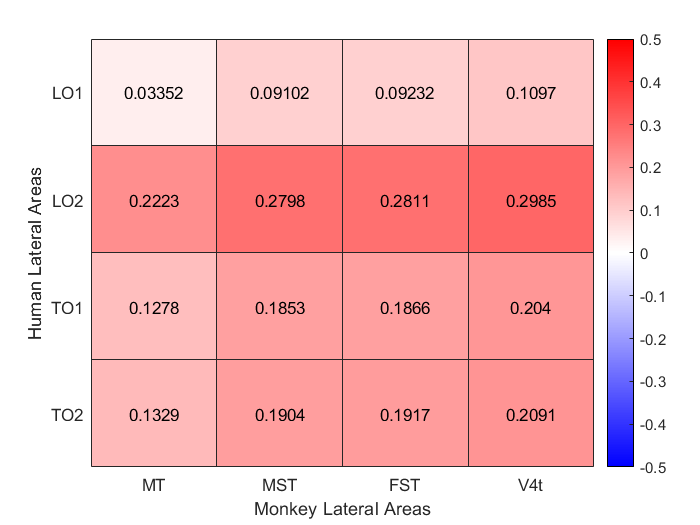

saveas(gcf,[save_folder,'\CrossSpecies\dorsal_diff.fig'])

% lateral rois
nhuman = length(lateralrois_human);
nmonkey = length(lateralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(lateralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(lateralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
    end
end

yvalues = all_labels_human(lateralrois_human);
xvalues = all_labels_monkey(lateralrois_monkey+5);

figure;
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Lateral Areas')
ylabel('Human Lateral Areas')
saveas(gcf,[save_folder,'\CrossSpecies\lateral_diff.png'])

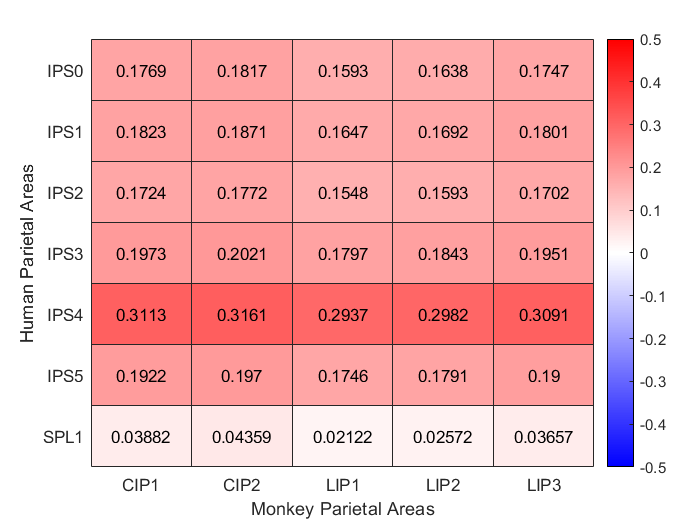

saveas(gcf,[save_folder,'\CrossSpecies\lateral_diff.fig'])


% parietal rois
nhuman = length(parietalrois_human);
nmonkey = length(parietalrois_monkey+5);

roi_diff = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(parietalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(parietalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
    end
end

yvalues = all_labels_human(parietalrois_human);
xvalues = all_labels_monkey(parietalrois_monkey+5);

figure;
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Parietal Areas')
ylabel('Human Parietal Areas')
saveas(gcf,[save_folder,'\CrossSpecies\parietal_diff.png'])

saveas(gcf,[save_folder,'\CrossSpecies\parietal_diff.fig'])

